clc; clear; close all;
load('FC_patch_data.mat')
f = @(x, y) sin(30*(x-1)).*cos(30*(y));

S_FC_patch = FC_patches{5};

[patch_X, patch_Y] = S_FC_patch.xy_mesh;

S_FC_patch.f_XY = f(patch_X, patch_Y);
S_FC_patch.eps_xy = 1e-15;
S_FC_patch.eps_xi_eta = 1e-15;

R.f_R = zeros(R.n_y, R.n_x);

R_patch_idxs = R.interpolate_patch(S_FC_patch, 6, 10);

R_patch_msk = false(size(R.f_R)); R_patch_msk(R_patch_idxs) = true;

R.f_R(~R_patch_msk) = nan;

err = abs(R.f_R - f(R.R_X, R.R_Y));
[~, max_idx] = max(err(:))

max_idx = 33376862

x = R.R_X(max_idx); y = R.R_Y(max_idx);

[patch_X, patch_Y] = S_FC_patch.xy_mesh;
[patch_XI, patch_ETA] = S_FC_patch.xi_eta_mesh;

[xi, eta, converged] = S_FC_patch.inverse_M_p(x, y, nan)

xi = 0.4697

eta = -0.0067

converged = logical
   1



err_no_scal = abs(S_FC_patch.locally_compute(xi, eta, 10) - f(x, y))

err_no_scal = 3.1947e-14


h_xi = (S_FC_patch.xi_end-S_FC_patch.xi_start)/(S_FC_patch.n_xi-1);
h_eta = (S_FC_patch.eta_end-S_FC_patch.eta_start)/(S_FC_patch.n_eta-1);

i = floor((xi-S_FC_patch.xi_start)/h_xi) + 1

i = 2263

j = floor((eta-S_FC_patch.eta_start)/h_eta) + 1

j = 1

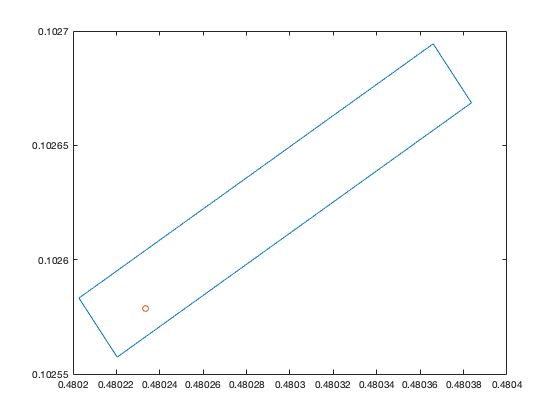


cell_corners_X = [patch_X(j, i); patch_X(j+1, i); patch_X(j+1, i+1); patch_X(j, i+1)];
cell_corners_Y = [patch_Y(j, i); patch_Y(j+1, i); patch_Y(j+1, i+1); patch_Y(j, i+1)];

in_cell = inpolygon_mesh(R.R_X, R.R_Y, [cell_corners_X; cell_corners_X(1)], [cell_corners_Y; cell_corners_Y(1)]);

figure;
plot([cell_corners_X; cell_corners_X(1)], [cell_corners_Y; cell_corners_Y(1)]);
hold on;
scatter(x, y)

M = 10;

r = 1;
h_xi_r = h_xi/r;
h_eta_r = h_eta/r;

h_xi_vpa = vpa(1)/vpa(S_FC_patch.n_xi-1)

$$h\_xi\_vpa = 0.00020764119601328903654485049833887$$

h_xi_r_vpa = h_xi_vpa/vpa(r);

h_eta_vpa = vpa(h_eta)

$$h\_eta\_vpa = 0.00003125$$

h_eta_r_vpa = h_eta_vpa/vpa(r)

$$h\_eta\_r\_vpa = 0.00003125$$


r_i = floor((xi - patch_XI(j, i))/h_xi_r);
r_j = floor((eta - patch_ETA(j, i))/h_eta_r);

xi_0_vpa = (i-1)*h_xi_vpa + h_xi_r_vpa*r_i

$$xi\_0\_vpa = 0.46968438538205980066445182724252$$

eta_0_vpa = (j-1)*h_eta_vpa-(S_FC_patch.n_eta-1)*h_eta_vpa + h_eta_r_vpa*r_j

$$eta\_0\_vpa = -0.00675$$


xi_0 = patch_XI(j, i)+h_xi_r*r_i

xi_0 = 0.4697

eta_0 = patch_ETA(j, i)+h_eta_r*r_j

eta_0 = -0.0068


R_i = round((x - R.x_start)/R.h);
R_j = round((y-R.y_start)/R.h);

xi_vpa = vpa(xi)

$$xi\_vpa = 0.46970829270721925485787551224348$$

eta_vpa = vpa(eta)

$$eta\_vpa = -0.0067397716727137912257061813647852$$


xy_vpa = S_FC_patch.M_p(xi_vpa, eta_vpa);
x_vpa = xy_vpa(1);
y_vpa = xy_vpa(2);

v_guess = S_FC_patch.J([xi_0;eta_0]) \ -double(transpose(S_FC_patch.M_p(xi_0_vpa, eta_0_vpa)) - [x_vpa; y_vpa]);

% xi_scal = v_guess(1)+xi_0
% eta_scal = v_guess(2)+eta_0

xi_scal = double(xi_vpa);
eta_scal = double(eta_vpa);

% double(vpa(v_guess(1))+vpa(xi_0) - xi_test)
% double(vpa(v_guess(2))+vpa(eta_0) - eta_test)

xi_j = floor((xi_scal-S_FC_patch.xi_start)/h_xi);
eta_j = floor((eta_scal-S_FC_patch.eta_start)/h_eta);

half_M =  floor(M/2);
if mod(M, 2) ~= 0
    interpol_xi_j_mesh = transpose(xi_j-half_M:xi_j+half_M);
    interpol_eta_j_mesh = transpose(eta_j-half_M:eta_j+half_M);
else
    interpol_xi_j_mesh = transpose(xi_j-half_M+1:xi_j+half_M);
    interpol_eta_j_mesh = transpose(eta_j-half_M+1:eta_j+half_M);
end

interpol_xi_j_mesh = shift_idx_mesh(interpol_xi_j_mesh, 0, S_FC_patch.n_xi-1);
interpol_eta_j_mesh = shift_idx_mesh(interpol_eta_j_mesh, 0, S_FC_patch.n_eta-1);

% interpol_xi_mesh = h_xi*(interpol_xi_j_mesh-i+1-r_i/r);
% interpol_eta_mesh = h_eta*(interpol_eta_j_mesh-j+1-r_j/r);

interpol_xi_mesh = h_xi_vpa*(interpol_xi_j_mesh);
interpol_eta_mesh = h_eta_vpa*(interpol_eta_j_mesh)-(S_FC_patch.n_eta-1)*h_eta_vpa;

% first 1D interpolation
interpol_xi_exact = zeros(M, 1);
for horz_idx = 1:M
    interpol_val = S_FC_patch.f_XY(interpol_eta_j_mesh(horz_idx)+1, interpol_xi_j_mesh+1)'
    interpol_xi_exact(horz_idx) = barylag([interpol_xi_mesh, interpol_val], xi_vpa);
end

interpol_val =     0.0945
    0.0994
    0.1043
    0.1092
    0.1141
    0.1190
    0.1238
    0.1287
    0.1336
    0.1385


interpol_val =     0.0940
    0.0989
    0.1038
    0.1087
    0.1136
    0.1184
    0.1233
    0.1282
    0.1331
    0.1379


interpol_val =     0.0935
    0.0984
    0.1033
    0.1082
    0.1130
    0.1179
    0.1228
    0.1277
    0.1325
    0.1374


interpol_val =     0.0930
    0.0979
    0.1028
    0.1076
    0.1125
    0.1174
    0.1223
    0.1272
    0.1320
    0.1369


interpol_val =     0.0925
    0.0974
    0.1022
    0.1071
    0.1120
    0.1169
    0.1218
    0.1266
    0.1315
    0.1364


interpol_val =     0.0920
    0.0968
    0.1017
    0.1066
    0.1115
    0.1164
    0.1212
    0.1261
    0.1310
    0.1359


interpol_val =     0.0914
    0.0963
    0.1012
    0.1061
    0.1110
    0.1159
    0.1207
    0.1256
    0.1305
    0.1353


interpol_val =     0.0909
    0.0958
    0.1007
    0.1056
    0.1105
    0.1153
    0.1202
    0.1251
    0.1300
    0.1348


interpol_val =     0.0904
    0.0953
    0.1002
    0.1051
    0.1099
    0.1148
    0.1197
    0.1246
    0.1294
    0.1343


interpol_val =     0.0899
    0.0948
    0.0997
    0.1045
    0.1094
    0.1143
    0.1192
    0.1240
    0.1289
    0.1338


interpol_xi_exact

interpol_xi_exact =     0.1146
    0.1141
    0.1136
    0.1131
    0.1126
    0.1121
    0.1115
    0.1110
    0.1105
    0.1100


 % second 1D interpolation
f_xy = barylag([interpol_eta_mesh, interpol_xi_exact], eta_vpa);

err_scal = abs(double(f_xy) - f(double(x_vpa), double(y_vpa)))

err_scal = 2.8658e-14

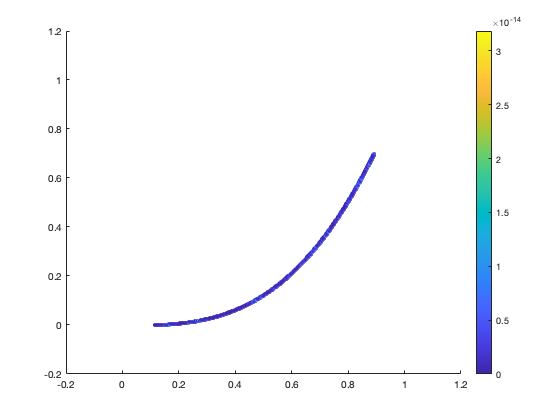

figure;
scatter(R.R_X(:), R.R_Y(:), 10, err(:), 'filled');
colorbar;

R_j_m = round((-y-R.y_start)/R.h);
err_m = err(R_j_m+1, R_i+1)

Index in position 1 is invalid. Array indices must be positive integers or logical values.


[xi_p, eta, converged] = S_FC_patch.inverse_M_p(x, -y, nan)

% j to the immediate left of point
xi_j = floor((xi_p-S_FC_patch.xi_start)/h_xi);
eta_j = floor((eta-S_FC_patch.eta_start)/h_eta);

half_M =  floor(M/2);
if mod(M, 2) ~= 0
    interpol_xi_j_mesh = transpose(xi_j-half_M:xi_j+half_M);
    interpol_eta_j_mesh = transpose(eta_j-half_M:eta_j+half_M);
else
    interpol_xi_j_mesh = transpose(xi_j-half_M+1:xi_j+half_M);
    interpol_eta_j_mesh = transpose(eta_j-half_M+1:eta_j+half_M);
end

interpol_xi_mesh = h_xi*interpol_xi_j_mesh + S_FC_patch.xi_start;
interpol_eta_mesh = h_eta*interpol_eta_j_mesh + S_FC_patch.eta_start;

interpol_mesh_m = S_FC_patch.f_XY(interpol_eta_j_mesh+1, interpol_xi_j_mesh+1)

[xi, eta, converged] = S_FC_patch.inverse_M_p(x, y, nan)

% j to the immediate left of point
xi_j = floor((xi-S_FC_patch.xi_start)/h_xi);
eta_j = floor((eta-S_FC_patch.eta_start)/h_eta);

half_M =  floor(M/2);
if mod(M, 2) ~= 0
    interpol_xi_j_mesh = flipud(transpose(xi_j-half_M:xi_j+half_M));
    interpol_eta_j_mesh = transpose(eta_j-half_M:eta_j+half_M);
else
    interpol_xi_j_mesh = flipud(transpose(xi_j-half_M+1:xi_j+half_M));
    interpol_eta_j_mesh = transpose(eta_j-half_M+1:eta_j+half_M);
end

interpol_mesh = S_FC_patch.f_XY(interpol_eta_j_mesh+1, interpol_xi_j_mesh+1)

interpol_xi_exact = zeros(M, 1);
for horz_idx = 1:M
    interpol_val = S_FC_patch.f_XY(interpol_eta_j_mesh(horz_idx)+1, interpol_xi_j_mesh+1)';
    interpol_xi_exact(horz_idx) = barylag([interpol_xi_mesh, interpol_val], xi_p);
end
 % second 1D interpolation
f_xy = barylag([interpol_eta_mesh, interpol_xi_exact], eta)

f = @(x, y) sin(30*(x-1)).*cos(30*(y));
f(x, y)

abs(f_xy - f(x, y))

interpol_mesh_m - interpol_mesh